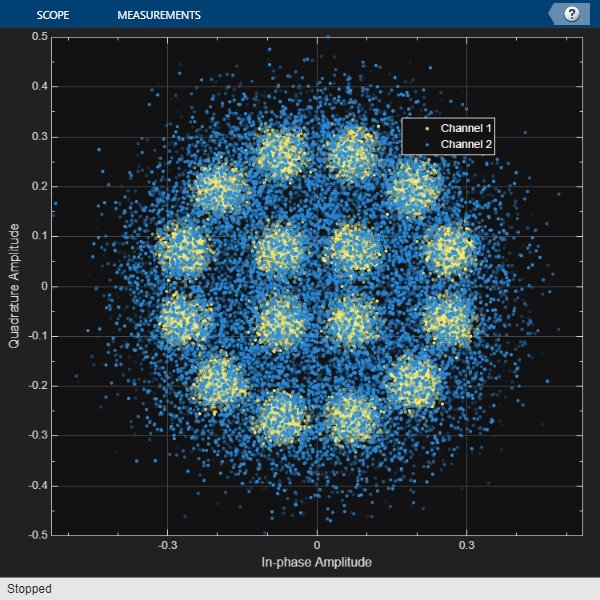



s2WaveGen = dvbs2WaveformGenerator;  % generator class object
s2WaveGen.MODCOD = 21;               % modulation type : 16APSK 5/6
s2WaveGen.DFL = 39690;
s2WaveGen.HasPilots = true;          % using pilots
numPkts = s2WaveGen.MinNumPackets*numFrames;

data=raw_data_generator(numPkts); 
waveform = s2WaveGen(data);

waveform_noise=awgn_channel(waveform); % awgn channel


sps = s2WaveGen.SamplesPerSymbol;
constel = comm.ConstellationDiagram('ColorFading',true, ...
    'ShowTrajectory',0, ...
    'SamplesPerSymbol',sps, ...
    'ShowReferenceConstellation',false, ...
    'NumInputPorts',2,...
    'XLimits',[-0.5 0.5], 'YLimits',[-0.5 0.5]);
plHeaderLen = 90*sps;           % PL header length
constel(waveform(plHeaderLen+1:end),waveform_noise(plHeaderLen+1:end));
release(constel);

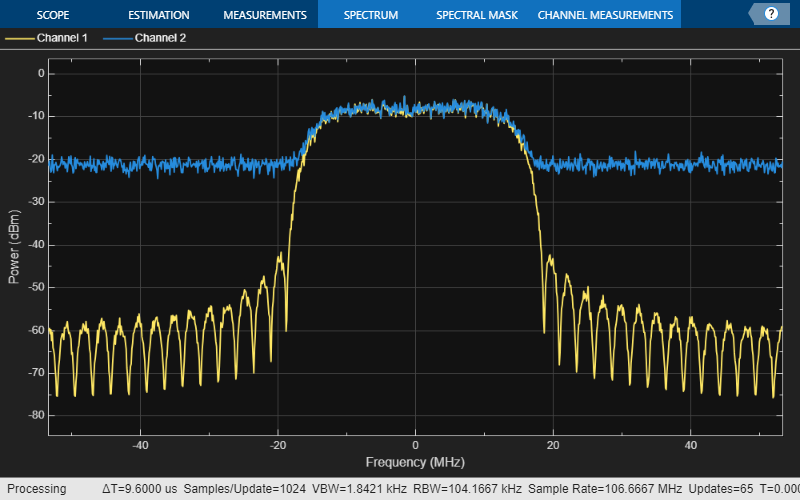


BW = 36e6;                 % Typical satellite channel bandwidth
Fsym = BW/(1+s2WaveGen.RolloffFactor);
Fsamp = Fsym*sps;
scope = spectrumAnalyzer('SampleRate',Fsamp);
scope(waveform,waveform_noise)